## Scale Model Lab Work

exampleData = readtable("Balloon Prelab Data 2020.xlsx");

exampleData.totalMass = (exampleData.BalloonMass_g_ + exampleData.PayloadMass__forNeutralBuoyancy__g_) / 1000;
exampleData(4:5,:) = [];
exampleData(:,1) = []; % get rid of extra rows/columns

R = 287; % gas constant for air [J/kg*K]
g = 9.81; % acceleration due to gravity [m/s^2]

Convert to metric

exampleData.TankLength_in_ = str2double(exampleData.TankLength_in_) ./ 39.37; % conver to meters
exampleData.TankWidth_in_= exampleData.TankWidth_in_ ./ 39.37;
exampleData.WaterHeightDisplacement_mm_ = str2double(exampleData.WaterHeightDisplacement_mm_) ./ 1000;

Find volume of balloon

exampleData.Volume = exampleData.WaterHeightDisplacement_mm_ .* exampleData.TankWidth_in_ .* exampleData.TankLength_in_;

Convert from hPa to Pa

exampleData.PILOTPressure_hPa_ = str2double(exampleData.PILOTPressure_hPa_) .* 100;

Convert from F to C

exampleData.PILOTTemp__F_ = (str2double(exampleData.PILOTTemp__F_) - 32) * (5/9) + 273.15;

Find air density using rho = P / (R * T)

exampleData.airDensity = exampleData.PILOTPressure_hPa_ ./ (R * (exampleData.PILOTTemp__F_));

Find buoyant force using F = rho * g * V

exampleData.buoyantF = exampleData.airDensity .* g .* exampleData.Volume;

Determine gas mass

exampleData.gasMass_g = ((exampleData.buoyantF ./ g) - exampleData.totalMass) .* 1000

exampleData = 3×17 table
    BalloonNumber    BalloonMass_g_    StringMass_g_    AdditionalMass_g_    PayloadMass__forNeutralBuoyancy__g_    PILOTTemp__F_    PILOTPressure_hPa_    BalloonDiameter_in_    MaxBalloonThickness_in_    WaterHeightDisplacement_mm_    TankLength_in_    TankWidth_in_    totalMass     Volume     airDensity    buoyantF    gasMass_g
    _____________    ______________    _____________    _________________    ___________________________________    _____________    __________________    ___________________    _______________________

gasMass = exampleData.gasMass_g

gasMass =     1.2788
    1.6892
    0.9473



totalMass = exampleData.BalloonMass_g_ + exampleData.PayloadMass__forNeutralBuoyancy__g_ + exampleData.gasMass_g

totalMass =    11.9338
   12.7862
   11.6903


fractionalShell = mean(exampleData.BalloonMass_g_ ./ totalMass)

fractionalShell = 0.7904

fractionalGas = mean(exampleData.gasMass_g ./ totalMass)

fractionalGas = 0.1068

fractioanlPayload = mean(exampleData.PayloadMass__forNeutralBuoyancy__g_ ./ totalMass)

fractioanlPayload = 0.1028


ShellMass = exampleData.BalloonMass_g_

ShellMass =     9.5690
    9.5530
    9.6120


Payload = exampleData.PayloadMass__forNeutralBuoyancy__g_

Payload =     1.0860
    1.5440
    1.1310


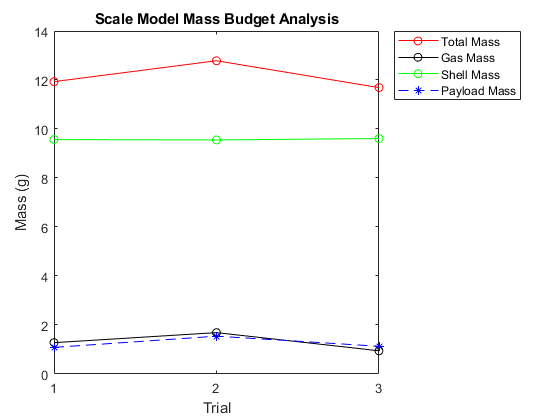


plot(totalMass,"r-o")
hold on
plot(gasMass,"k-o")
hold on
plot(ShellMass,"g-o")
hold on
plot(Payload,"b--*")
hold on
title("Scale Model Mass Budget Analysis")
xticks(0:3)
xlabel("Trial")
ylabel("Mass (g)")
hold off
legend("Total Mass","Gas Mass","Shell Mass","Payload Mass","Location","bestoutside")